sentFile = ["1_sent.dat"
    "1_sent_b.dat"
    "2_rx_sent.dat"
    ];

sent_cnt = length(sentFile);

recvFile = ["1_recv.dat"
    "1_recv_b.dat"
    "2_rx_recv.dat"
    ];
    
recv_cnt = length(recvFile);

nretx = [];
result = [];
delay = [];
diversity = [];
snr= [] ;
rssi = [];

recv_len = [];
for cnt = 1:1:sent_cnt
    
    sent_array= csvread(sentFile(cnt));
    recv_array = csvread(recvFile(cnt));
    
    
    nretx = [nretx mean(sent_array(:,1))];
    result = [result mean(sent_array(:,2))];
    delay = [delay mean(sent_array(:,3))];
    
    diversity = [diversity mean(recv_array(:,1))];
    snr = [snr mean(recv_array(:,2))];
    rssi = [rssi mean(recv_array(:,3))];
    
    recv_len = [recv_len length(recv_array')]
end

recv_len = 993

recv_len =    993   818


recv_len =    993   818   922


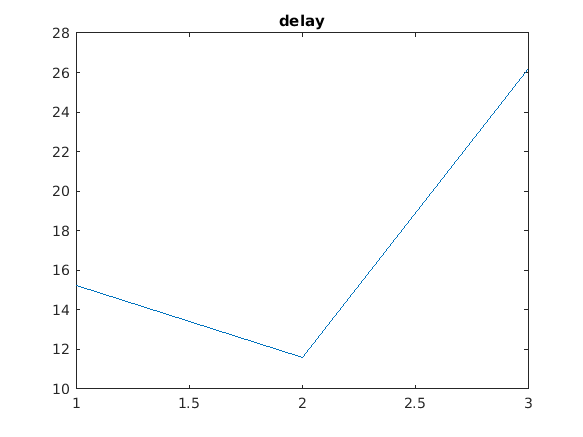



plot(delay);
title("delay");

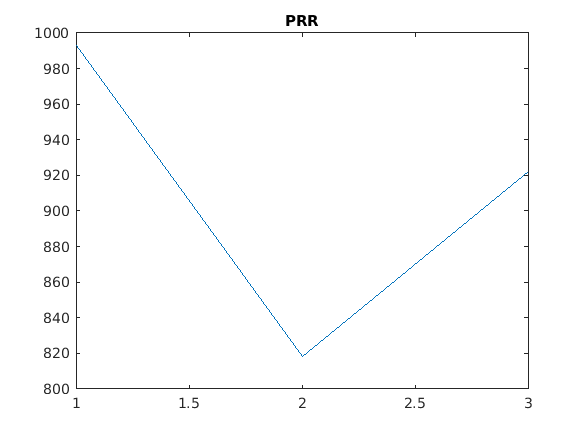

plot(recv_len);
title("PRR");

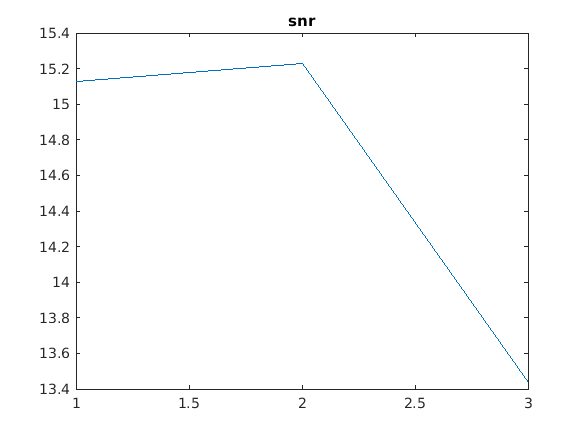

plot(snr);
title("snr");

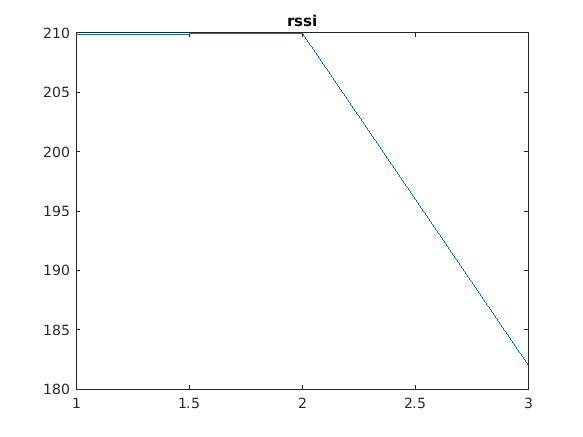

plot(rssi);
title("rssi");

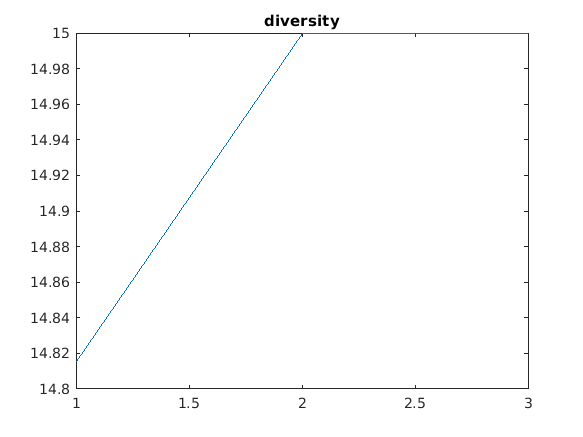

plot(diversity);
title("diversity");